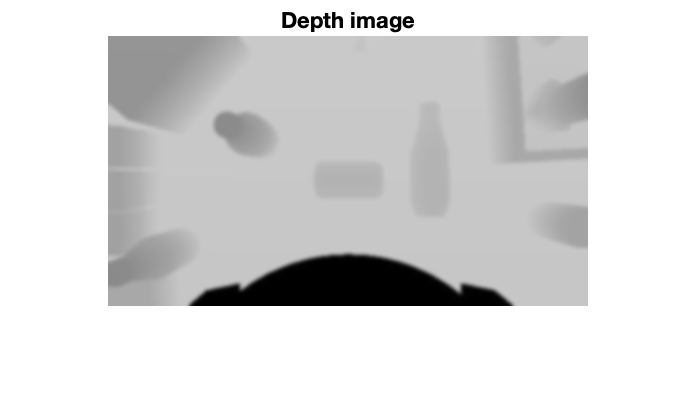

w = warning ('on','all');
warning(w)

% Load images ----------
img = imread('imgs/rgb.jpg'); % RGB image
I = imread('imgs/depth.jpg'); % Intensity images  1 Channel 

% Low Pass Filter (sigma = 2)
I = imgaussfilt(I, 2); 


imshow(I);
title("Depth image")

## Get Regions

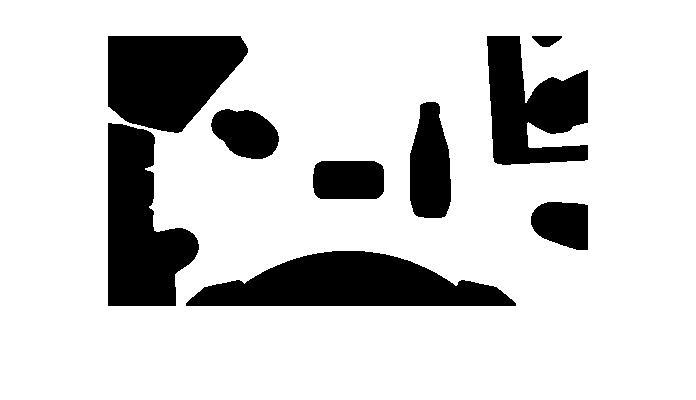

BW = imbinarize(I, 0.76); % Experimental threshold
imshow(BW); 

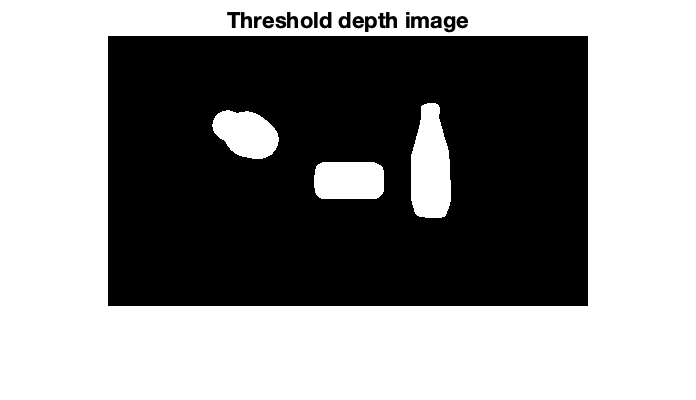

% Clean iamge 
BW = uint8(BW) * 255; 

SE = strel("square", 2); 
BW = imdilate(BW, SE); 

iminvert = @(I) 255 - I;  % Invert Uint8 imgs
BW = iminvert(BW); 
BW = imclearborder(BW); 
imshow(BW); 
title("Threshold depth image"); 

## Region Properties

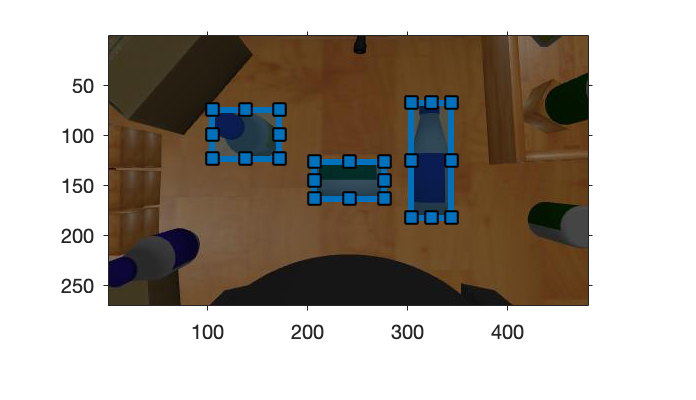

BW_region = BW ~= 0; % Re binarize img

s = regionprops(BW_region, "BoundingBox");
bbox = cat(1, s.BoundingBox); 

imshow(img);
hold on; 
drawBoxes(bbox); 
axis on;

hold off;

## Create a Point cloud

Create a point cloud from the 3-D caracterization of the space from the RGB-D sensor raw images. Each ROI is based in the segmentation process before. 

% Get cylinder model 
boxID = 2;

model = getMeshFromROI(img, I, BW_region, bbox( boxID, :), 0.01)

model =   cylinderModel with properties:

     Parameters: [2 18 188 66 18 188 10]
         Center: [34 18 188]
    Orientation: [64 0 0]
         Height: 64
         Radius: 10


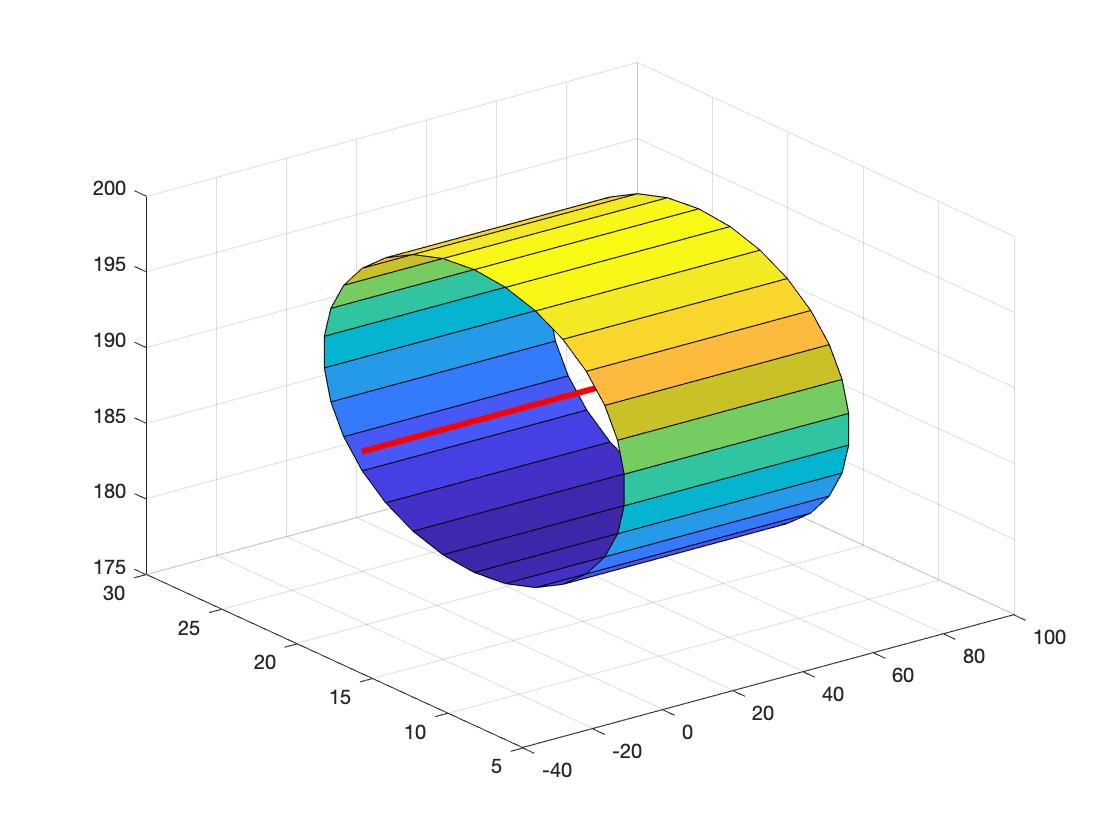

% Graph the cylinder 
figure; 
plot(model); 
hold on; 

center = model.Center;
orientation = model.Orientation;

% Positons for the axis 
r_0 = center + orientation; 
r_1 = center - orientation; 

ref_axis_pts = [r_0; r_1];
X = ref_axis_pts(:, 1);
Y = ref_axis_pts(:, 2);
Z = ref_axis_pts(:, 3);

plot3(X, Y, Z, "LineWidth",3, "Color","red"); 
hold off; 

## Locate the axis in the img

% get de pc of the RGB image 
[pts] = createPC(img, I)

pts =   pointCloud with properties:

     Location: [129600×3 double]
        Count: 129600
      XLimits: [-239 240]
      YLimits: [0 269]
      ZLimits: [-203 0]
        Color: [129600×3 uint8]
       Normal: []
    Intensity: []


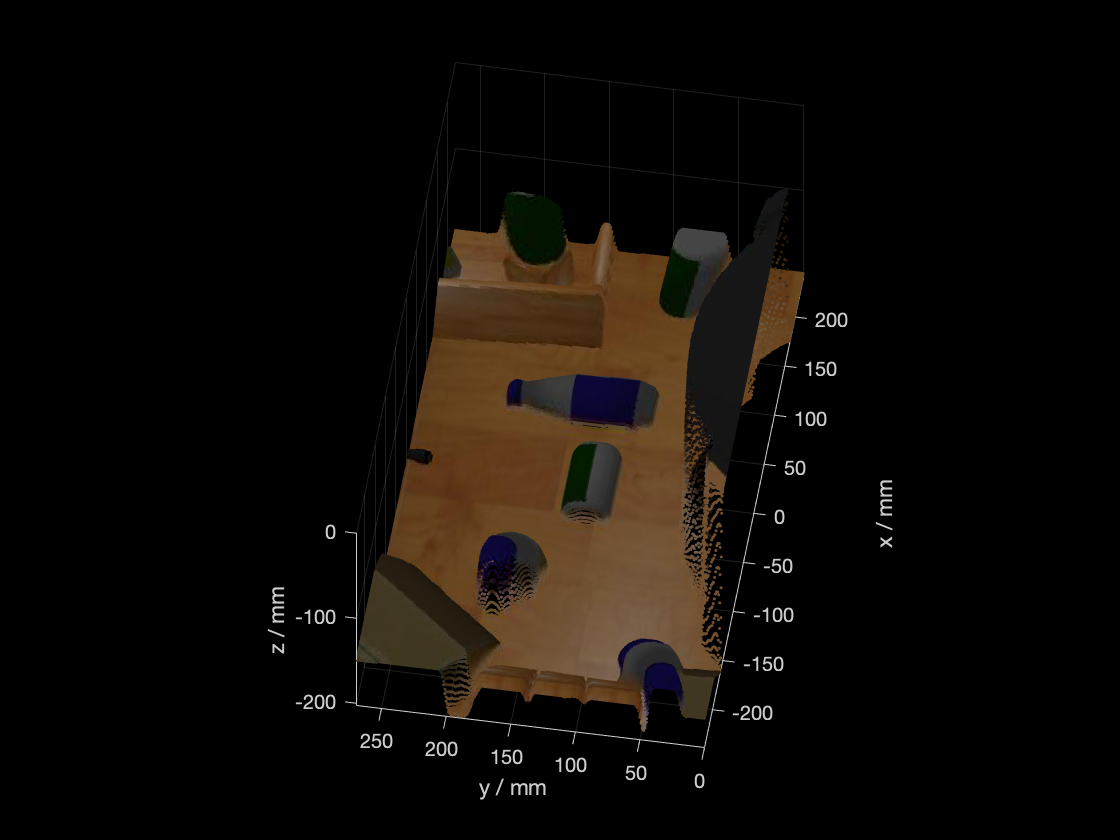

% Show 
pcshow(pts, 'VerticalAxisDir', "Up")
xlabel("x / mm"); 
ylabel("y / mm"); 
zlabel("z / mm"); 

hold on; 

box_interest = bbox(boxID, 1:4); % Get a box from a ROI


[Ymax, Xmax, chan] = size(img); 

% Corner of box --------
box_roi_X = box_interest(1) - Xmax / 2;
box_roi_Y = R -  box_interest(2) - box_interest(4); 

Unrecognized function or variable 'R'.


box_corner = [box_roi_X, box_roi_Y];

% plot3(X(:), Y(:), Z(:), '-', 'LineWidth', 3)
hold on; 

% Draw the axis v:

center = model.Center; 
orientation = model.Height * model.Orientation / (norm(model.Orientation)); 

% Reflection in xy-plane
center = center + [box_corner 0]; 
% Extremes of axis 
p_0 = (center - orientation) .* [1, 1, -1]; 
p_1 = (center + orientation) .* [1, 1, -1] ; 

axis_x = [p_0(1), p_1(1)];
axis_y = [p_0(2), p_1(2)];
axis_z = [p_0(3), p_1(3)];
plot3(axis_x, axis_y, axis_z, "LineWidth", 5);
hold off; 




